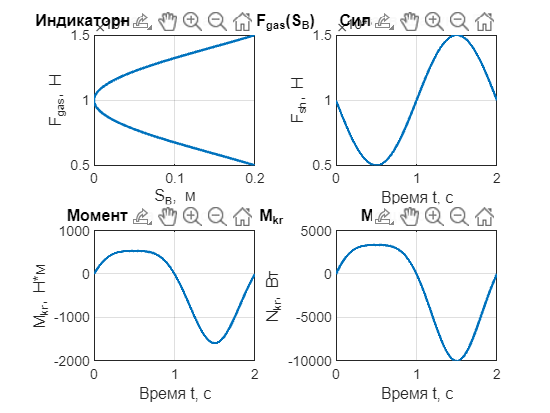

% Параметры для расчета динамических характеристик
P0 = 1e6; % Давление газа, Па (примерное значение)
A_piston = 0.01; % Площадь поршня, м² (примерное значение)
m_piston = 2; % Масса поршня, кг (примерное значение)

% Расчет времени (если еще не определено)
N = length(S_B); % Количество точек
T = 2; % Длительность моделирования
t = linspace(0, T, N);

% Убедимся, что все массивы имеют одинаковый размер
% Если A_B не определен, создадим его (пример)
if ~exist('A_B', 'var') || length(A_B) ~= N
    A_B = zeros(1, N); % Замените на реальное ускорение
end

% Если phi1 не определен, создадим его
if ~exist('phi1', 'var') || length(phi1) ~= N
    phi1 = linspace(0, 2*pi, N);
end

% Если omega не определена, создадим ее
if ~exist('omega', 'var')
    omega = 2*pi/T; % Постоянная угловая скорость
end

% Расчет динамических параметров
F_gas = P0 * A_piston * (1 - 0.5 * sin(2*pi*t/T)); % Пример: сила от давления газа
F_inertia = -m_piston * A_B; % Сила инерции поршня
F_sh = F_gas + F_inertia; % Суммарная сила в шатуне (упрощенно)

% Расчет момента на кривошипе (упрощенная модель)
% Используем поэлементные операции
M_kr = F_sh .* r .* sin(phi1) ./ sqrt(1 - (r/l * sin(phi1)).^2);

% Расчет мощности (omega может быть скаляром или вектором)
if isscalar(omega)
    N_kr = M_kr * omega;
else
    N_kr = M_kr .* omega;
end

% Построение индикаторной диаграммы
figure('Name', 'Динамические характеристики');
subplot(2,2,1);
plot(S_B, F_gas, 'LineWidth', 1.5);
grid on; title('Индикаторная диаграмма: F_{gas}(S_B)');
xlabel('S_B, м'); ylabel('F_{gas}, Н');

% Построение других динамических параметров
subplot(2,2,2);
plot(t, F_sh, 'LineWidth', 1.5);
grid on; title('Сила в шатуне F_{sh}');
xlabel('Время t, с'); ylabel('F_{sh}, Н');

subplot(2,2,3);
plot(t, M_kr, 'LineWidth', 1.5);
grid on; title('Момент на кривошипе M_{kr}');
xlabel('Время t, с'); ylabel('M_{kr}, Н*м');

subplot(2,2,4);
plot(t, N_kr, 'LineWidth', 1.5);
grid on; title('Мощность N_{kr}');
xlabel('Время t, с'); ylabel('N_{kr}, Вт');